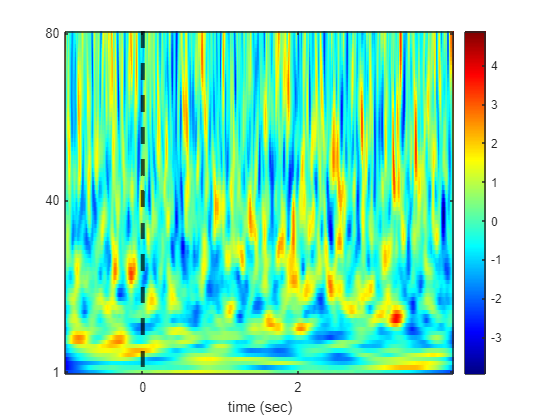

%now, plot the avg spectrogram across the trials

addpath C:\Users\ivans\Downloads\code;


count=1;

for x = 1:size(image,1)
    curr_patient_id = image.patient_id(x);

    if strcmp(curr_patient_id{1},'TWH173')==1

        image_start_unix_ms = int64(round(image.onset_timestamp(x)*1000));
        image_end_unix_ms = int64(round(image.termination_timestamp(x)*1000));

        eeg_curr_trial_start_ind(count) = find(Timestamps_ms==image_start_unix_ms);
        eeg_curr_trial_end_ind(count) = find(Timestamps_ms==image_end_unix_ms);
       
        count=count+1;
    end
end

image_ind = 1:40;
info = 'trial limits indices contain image onset/offset indices for all images. indices equal miliseconds relative to recording onset, if the sampling rate is 1000 hz'
save('trial_limits_ind','eeg_curr_trial_end_ind',"eeg_curr_trial_start_ind",'info','image_ind');